# Linear Discriminant Analysis (LDA) Model

Team name: CONP Apps

Group Members: Chelsea, Omar, Nico, Peyton

Course: BME 3053C Computer Applications for BME

Term: Fall 2020

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

clc; clear; close all;

Load training and testing data

load TrainData.mat
load TestData.mat

Creating the LDA model

lda = fitcdiscr(TrainData, 'State')

lda =   ClassificationDiscriminant
           PredictorNames: {'s2l'  'Int'}
             ResponseName: 'State'
    CategoricalPredictors: []
               ClassNames: {'N'  'P'}
           ScoreTransform: 'none'
          NumObservations: 40
              DiscrimType: 'linear'
                       Mu: [2×2 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


Make a prediction if the x-ray is normal or shows signs of pneumonia using the generated model

predictdata = predict(lda, TestData);

Compare the predictions to actual classifications

correctpredict = predictdata == TestData.State;

Calculate the accuracy of the predictions made by the model

accuracy = sum(correctpredict)/ numel(correctpredict);
percentaccuracy = accuracy*100;
disp('% accuracy');

% accuracy


disp(percentaccuracy);

    80



Calculate the misclassification rate of the predictions made by the model

misclass = predictdata ~= TestData.State;
misclassrate = sum(misclass) / numel(misclass);
disp('Misclassification rate');

Misclassification rate


disp(misclassrate);

    0.2000



Visualize the misclassified images

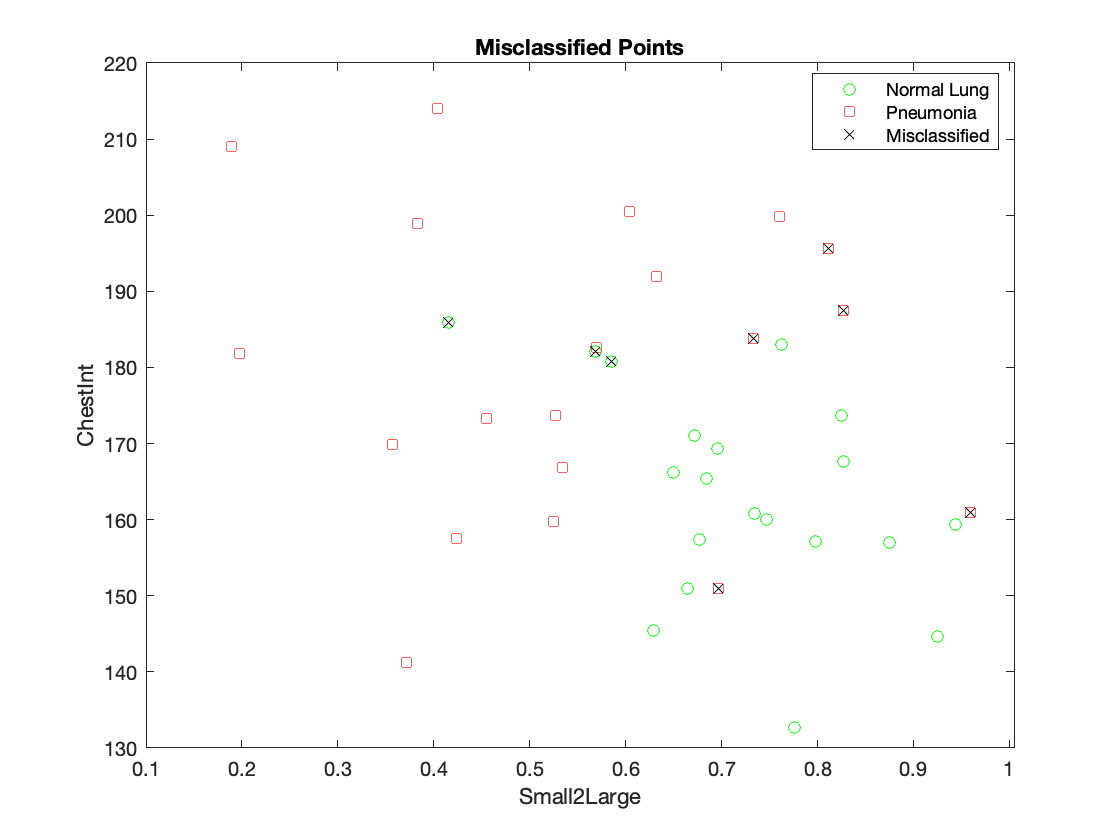

gscatter(TestData.s2l, TestData.Int, TestData.State, 'gr', 'os')
hold on;
plot(TestData.s2l(misclass), TestData.Int(misclass), 'kx');
hold off;
title('Misclassified Points');
xlabel('Small2Large');
ylabel('ChestInt');
legend('Normal Lung','Pneumonia', 'Misclassified');

Create the confusion matrix

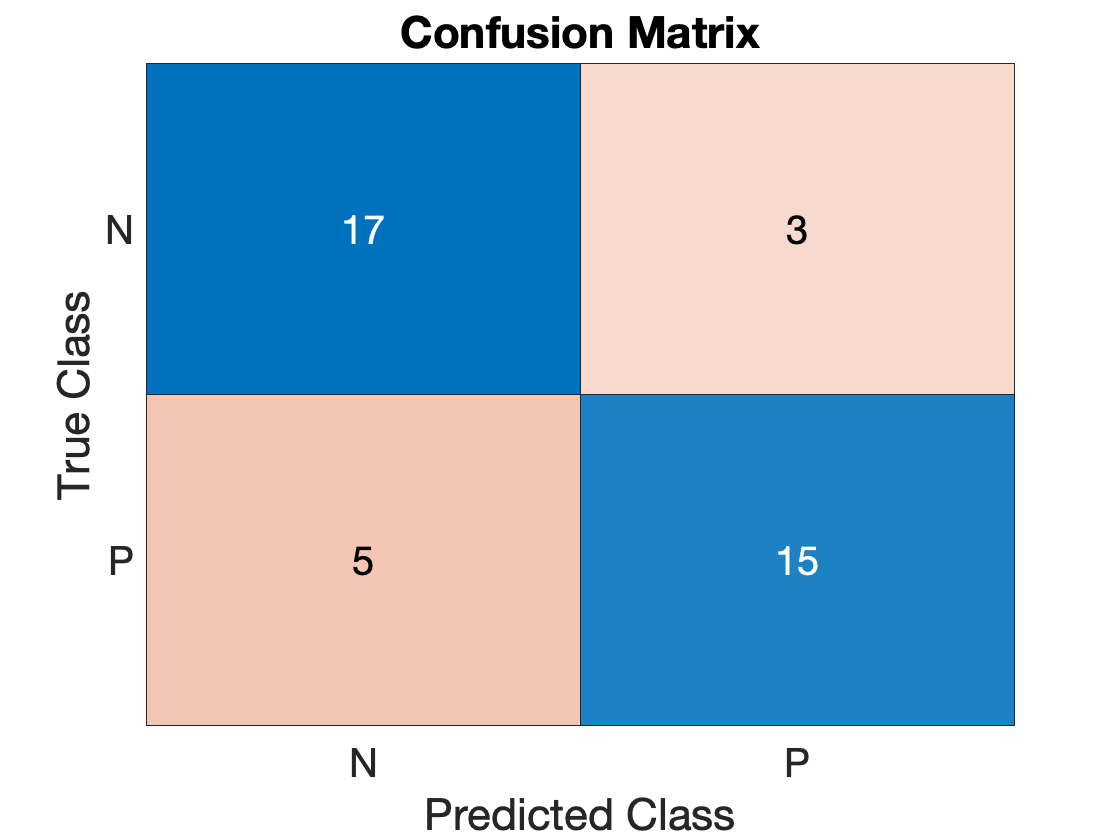

StateData = TestData.State;
StateData = cellstr(StateData);
CM = confusionchart(StateData, predictdata);
title('Confusion Matrix');
CM.FontSize = 20;